% Base paths and clearing
clear all
clc
addpath functions/SETUP/
addpath functions/SENSE/
addpath functions/ACT/

% Setup Pi
[robotPi, blinkLED]= SETUP_pi("192.168.16.68");

% Setup Servos
robotServos = I2C_Servo_pHAT(robotPi);
% Setup Sensors
[adcDevice1, adcDevice2] = SETUP_adc(robotPi);

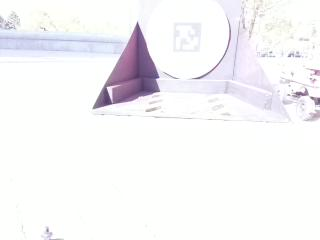

% Setup PiCam
robotCam = cameraboard(robotPi,'Resolution','320x240');
SETUP_piCam(robotCam);  

img = snapshotCustom(robotCam);

piCamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
figure(piCamWindow)
imshow(img,'Border','tight')

ACT_moveRover(robotServos,0,0)

joy = vrjoystick(1);

disp("Drive Safely!")

Drive Safely!



sonarData = zeros(8,4);
IRData = zeros(8,6);

% setup GPS
GPSData = zeros(1000,3);
neo = SETUP_gps(robotPi);


velocity = 0;
photoCount = 1;
sonarCount = 1;
IRCount = 1;
point = 1;
while 1

    
    velocity = -.69*axis(joy, 2);
    angle = 35*axis(joy,1);
    ACT_moveRover(robotServos,angle,velocity)
    %pan = 70*axis(joy,3)+90;
    %tilt = 30*axis(joy,5)+50;
    ACT_moveCam(robotServos,90,40);
    pause(.1)
    % Take PiCam Photo
    if (1 == button(joy,1))
        piIMG = snapshotCustom(robotCam);            % capture a pi camera image
        figure(piCamWindow)                          % go to camWindow fo imshow
        imshow(piIMG,'Border',"tight")
        imwrite(piIMG, sprintf('images/Test5/LineFollow%g.jpg', photoCount), "jpg");
        photoCount = photoCount + 1;
    end
    
    if (1 == button(joy,6))
        ACT_moveCam(robotServos,90,40);
        
    end
    
    % Save Sonar Data
%     if (1 == button(joy,2))
%         curve = SENSE_IR(adcDevice1, adcDevice2)
%         sonarData(sonarCount, 1) = rawRangeData(6)
%         sonarData(sonarCount, 2) = input (['Enter actual distance to wall to the right, followed by Enter: ']);
%         pause(2)
%         sonarData(sonarCount, 3) = rawRangeData(7)
%         sonarData(sonarCount, 4) = input (['Enter actual distance to wall to the left, followed by Enter: ']);
%         pause(2)
%     end
    
%     % Save Sonar Data
%     if (1 == button(joy,2))
%         rawRangeData = SENSE_adc(adcDevice1, adcDevice2)
%         sonarData(sonarCount, 1) = rawRangeData(6)
%         sonarData(sonarCount, 2) = input (['Enter actual distance to wall to the right, followed by Enter: ']);
%         pause(2)
%         sonarData(sonarCount, 3) = rawRangeData(7)
%         sonarData(sonarCount, 4) = input (['Enter actual distance to wall to the left, followed by Enter: ']);
%         pause(2)
%     end
%     
%     % Save IR Data
%     if (1 == button(joy,4)
%         rawRangeData = SENSE_adc(adcDevice1, adcDevice2)
%         sonarData(sonarCount, 2:6) = rawRangeData(1:5)
%         sonarData(sonarCount, 1) = input (['Enter actual distance to object in front, followed by Enter: ']);
%         pause(2)
%     end
    if (-1)^point == 1
        [X,Y,heading] = SENSE_gps(neo);
        GPSData(point,1) = X;
        GPSData(point,2) = Y;
        GPSData(point,3) = heading;
    end

    
    point = point+1;
    pause(.1)
    

end